# Compute Basic Potential Flows

Much of the theory used to understand aerodynamic lift comes from very simply flows called potential flows, in which the friction, compressibility, and other effects are neglected. 

## Potential Flow Theory

For potential flow, the velocity vector field is considered both incompressible and irrotational, which can be expressed as:


$$\begin{array}{l}
\nabla \cdot \vec{u} =0\\
\nabla \times \vec{u} =0
\end{array}$$


And the pressure field is computed from the velocity field using Bernoulli's equation:


$$p=p_t -\frac{\rho_{\infty } }{2}{\left|\vec{u} \right|}^2$$


In order to derive an equation for the velocity which satisfies the conditions above, we can use the identity that the curl of the gradient of any scalar function is zero, or:


$$\nabla \times \nabla f=0$$


Then we can define a scalar function called the "velocity potential", $\phi$  as follows:

Start with our assumptions about an incompressible and irrotational vector field $\vec{u}$.

-  Write $\vec{u}$ as $\nabla\phi$, and then $\nabla \cdot \nabla \phi = 0$, due to incompressibility. This is Laplace's equation: $\nabla^2\phi = 0$. 

- The second equation is automatically satisfied due to the identity above: $\nabla \times \nabla \phi =0$.

Laplace's equation for the velocity potential $\phi$ can be solved subject to boundary conditions at the far field and the body.  Since this equation is a linear second-order differential equation, solutions can be superimposed to create new functions which are also solutions to the equation.  This approach is used to compose various flows of interest for understanding aerodynamics.

In the following sections, several basic potential flows are introduced.  Each one has a checkbox to enable or disable it from the combined flow field plots below.

## Calculating Streamlines using the Streamfunction

For 2D potential flows, a function called the **streamfunction**, $\psi$, can be determined that is orthogonal to the **potential function**, $\phi$, and has the property that contours of constant $\psi$ are aligned with the velocity field.  We can use this function to plot the flow field for potential flows and see the path of the velocity field.   We will use cylindrical coordinates to define most of these flows.

## Uniform Flow

Uniform flow is a solution for potential flow, in the form:

$\phi =V_{\infty } x\;$, for a uniform flow in the $X$ direction at speed $V_{\infty }$

And the corresponding streamfunction is defined as:

$\psi =V_{\infty } y$.

%Use symbolic math to represent the velocity potential function and streamfunction
syms x y r theta Vinf phi psi

%Uniform flow
uniform = true;
if uniform
    Vinf = 10;
    disp("In Cartesian coordinates:")
    displayFormula("phi = Vinf*x")
    displayFormula("psi = Vinf*y")

    % Convert to cylindrical coordinates
    disp("In cylindrical coordinates:")
    displayFormula("phi = Vinf*r*cos(theta)")
    displayFormula("psi = Vinf*r*sin(theta)")
else
    Vinf = 0;
end

In Cartesian coordinates:


$$\varphi =10\,x$$

$$\psi =10\,y$$

In cylindrical coordinates:


$$\varphi =10\,r\,\cos\left(\theta \right)$$

$$\psi =10\,r\,\sin\left(\theta \right)$$

## Source or Sink Flow

Potential flow with streamlines emanating from a point and traveling outward from that point is called source flow.  Similarly, sink flow is the same except the flow direction is inward, toward the point.  While this flow is not particularly meaningful by itself, it becomes useful when combined with uniform flow.  2D source or sink flow is defined in cylindrical coordinates as:

$\phi =\frac{\lambda }{2\pi }\ln \left(r\right)\;$,       and       $\psi =\frac{\lambda }{2\pi }\theta$,

where $\lambda$ is the strength of the source or sink, and has a positive value for a source or negative value for a sink.

% Add source (checked) or sink (unchecked) flow
addSource = false;
if addSource
    syms lambda source
    displayFormula("lambda_source = 25")
    lambdaSource = 25;
    displayFormula(["phi=Vinf*r*cos(theta)+lambdaSource/(2*pi)*log(r)"; ...
        "psi = Vinf*r*sin(theta)+lambdaSource/(2*pi)*theta"])
    psiBody = double(lambdaSource)/2.0;
else
    lambdaSource=0;
end

addSink = false; % At same location as source
if addSink
    syms lambda sink;
    displayFormula("lambda_sink = -25");
    lambdaSink = -25;
    lambda = lambdaSource+lambdaSink;
    displayFormula(["phi=Vinf*r*cos(theta)+lambda/(2*pi)*log(r)"; ...
        "psi = Vinf*r*sin(theta)+lambda/(2*pi)*theta"])
    psiBody = double(lambda)/2.0;
else
    lambda = lambdaSource;
end
if ~or(addSink,addSource)
    % No sources, no sinks
    lambda = 0;
end

## Doublet Flow

An interesting potential flow that results from taking a source and sink and bringing them asympotically close (while keeping the strength of the combination finite) is called a doublet.  It has traits of a source on one side and sink on the other.  The velocity potential and streamfunction for the doublet are:

$\phi =\frac{K}{2\pi }\frac{\cos \left(\theta \right)}{r}$ ,       and       $\psi =\frac{-K}{2\pi }\frac{\sin \left(\theta \right)}{r}$ ,

where $K$ is the strength of the doublet.   

% Add doublet flow, and compute the radius of a cylinder when superimposing
% doublet flow on uniform flow
addDoublet = false;
if addDoublet
    syms Kappa
    displayFormula("Kappa = 10")
    Kappa = 10;
    if lambda ~= 0 % Check if there is a source or a sink
        displayFormula("phi = Vinf*r*cos(theta) + lambda/(2*pi)*log(r) + Kappa/(2*pi)*cos(theta)/r")
        displayFormula("psi = Vinf*r*sin(theta) + lambda/(2*pi)*theta - Kappa/(2*pi)*sin(theta)/r")
    else
        displayFormula("phi = Vinf*r*cos(theta) + Kappa/(2*pi)*cos(theta)/r")
        displayFormula("psi = Vinf*r*sin(theta) - Kappa/(2*pi)*sin(theta)/r")
    end
    % For combined uniform plus doublet flow, the strength of the doublet determines a cylinder of radius R which is a stremaline
    if uniform
        R = sqrt(Kappa/(2*pi*Vinf))
        psiBody = double(subs(Vinf*r*sin(theta) + lambda/(2*pi)*theta - Kappa/(2*pi)*sin(theta)/r,{r,theta},{R,0.0}));
    else
        psiBody = 0;
    end
else
    Kappa = 0;
end

## Vortex Flow

An inviscid vortex is a potential flow in which all of the flow revolves around a point, while remaining irrotational (except at the origin).  This models the effect of rotating flows in a way which is useful for understanding aerodynamic lift.   The velocity potential and streamfunction for vortex flow are:

$\phi =\frac{-\Gamma }{2\pi }\theta \;$,       and      $\psi =\frac{\Gamma }{2\pi }\ln \left(r\right)$ ,

where $\Gamma$ is the strength of the vortex.   

addVortex = false;
if addVortex
    syms Gamma
    displayFormula("Gamma = 20")
    Gamma = 20;
    if lambda ~= 0 && Kappa ~= 0 % Check if there is a source or a sink and a doublet
        displayFormula("phi = Vinf*r*cos(theta) + lambda/(2*pi)*log(r) + Kappa/(2*pi)*cos(theta)/r - Gamma/(2*pi)*theta")
        displayFormula("psi = Vinf*r*sin(theta) + lambda/(2*pi)*theta - Kappa/(2*pi)*sin(theta)/r + Gamma/(2*pi)*log(r)")
    elseif lambda ~= 0
        displayFormula("phi = Vinf*r*cos(theta) + lambda/(2*pi)*log(r)- Gamma/(2*pi)*theta")
        displayFormula("psi = Vinf*r*sin(theta) + lambda/(2*pi)*theta + Gamma/(2*pi)*log(r)")
    elseif Kappa ~= 0
        displayFormula("phi = Vinf*r*cos(theta) + Kappa/(2*pi)*cos(theta)/r - Gamma/(2*pi)*theta")
        displayFormula("psi = Vinf*r*sin(theta) - Kappa/(2*pi)*sin(theta)/r + Gamma/(2*pi)*log(r)")
    else
        displayFormula("phi = Vinf*r*cos(theta)  - Gamma/(2*pi)*theta")
        displayFormula("psi = Vinf*r*sin(theta) + Gamma/(2*pi)*log(r)")
    end
    % When combined with uniform flow and a doublet, the streamline at the body can be computed using r=R
    if (uniform && addDoublet)
        psiBody = double(subs(Vinf*r*sin(theta) + lambda/(2*pi)*theta - Kappa/(2*pi)*sin(theta)/r + Gamma/(2*pi)*log(r),{r,theta},{R,0.0}));
    else
        psiBody = 0;
    end
else
    Gamma = 0;
end

## Plot the Velocity Potential and Streamfunction

Next, we create plots of the selected potential flow, using a cylindrical domain.

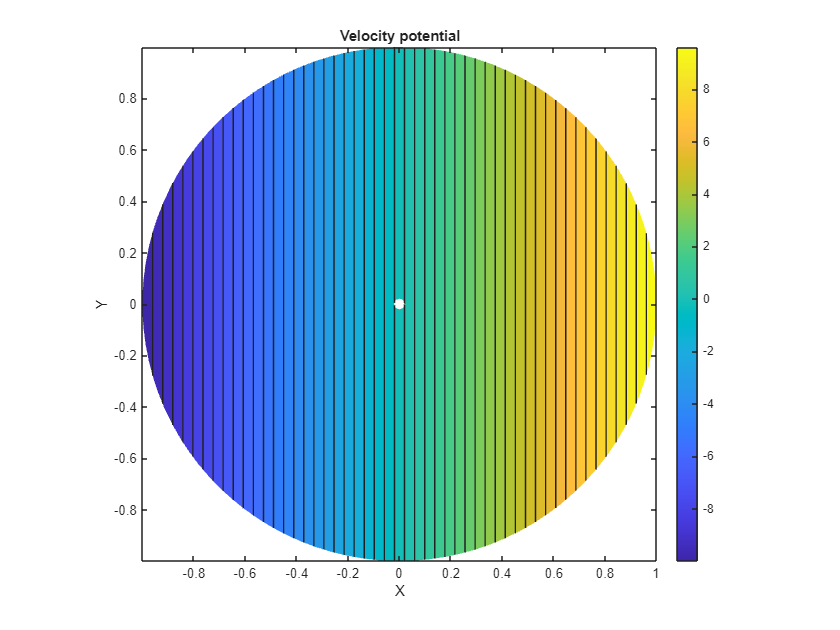

% Putting it all together
phi = Vinf*r*cos(theta) + lambda/(2*pi)*log(r) + Kappa/(2*pi)*cos(theta)/r - Gamma/(2*pi)*theta;
psi = Vinf*r*sin(theta) + lambda/(2*pi)*theta - Kappa/(2*pi)*sin(theta)/r + Gamma/(2*pi)*log(r);

%Create plot data in cylindrical coordinates in specified range of r

% Create r,theta grid for contour plots
rMin = 0.02;
rMax = 1;
if addDoublet
    % Since this flow defines a cylinder, create the plot from the cylinder
    % surface outward 5 radii
    rMin = double(R);
    rMax = 5*rMin;
end
rVals = linspace(rMin,rMax,100);
thetaVals = linspace(0,2*pi,100);
[rGrid, thetaGrid] = meshgrid(rVals,thetaVals);
[xGrid, yGrid] = pol2cart(thetaGrid,rGrid);

% Compute the function values for velocity potential in cylindrical coordinates
% by substituting r and theta with their arrays of discrete values
phiVals = double(subs(phi, {r, theta}, {rGrid, thetaGrid}));

% Create a filled contour plot of velocity potential for this flow
contourf(xGrid,yGrid,phiVals,50)
xlabel("X")
ylabel("Y")
title("Velocity potential")
axis equal
colorbar

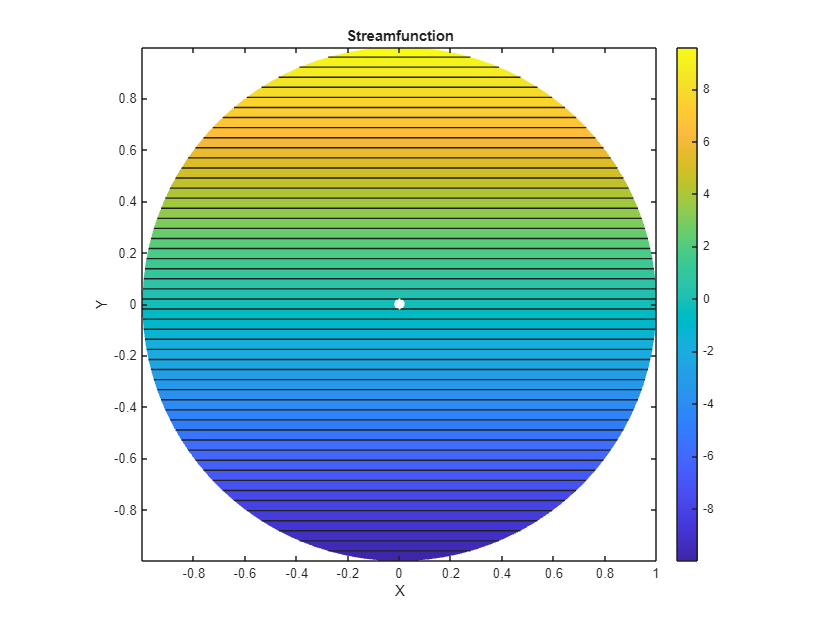

% Similarly, plot the streamfunction using a filled contour plot.  Add a
% streamline for the body
psiVals = double(subs(psi, {r, theta}, {rGrid, thetaGrid}));
contourf(xGrid,yGrid,psiVals,50)
if addSource
    hold on
    contour(xGrid,yGrid,psiVals,[-psiBody,psiBody],"-k")
end
if addDoublet
    hold on
    contour(xGrid,yGrid,psiVals,[psiBody,psiBody],"-k")
end
hold off
xlabel("X")
ylabel("Y")
title("Streamfunction")
axis equal
colorbar

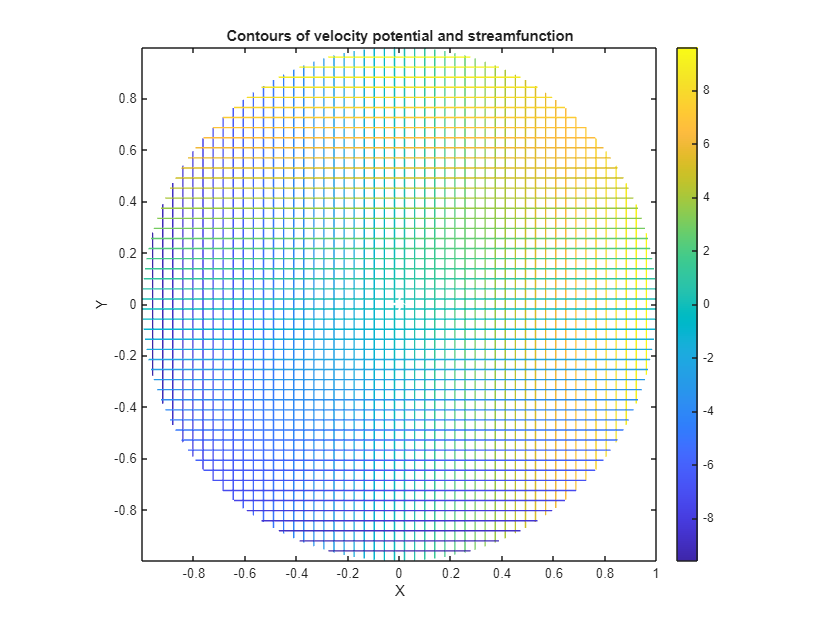

% Next we can plot the two functions together to show that they are orthogonal
contour(xGrid,yGrid,phiVals,50)
hold on;
contour(xGrid,yGrid,psiVals,50)
if addSource
    hold on
    contour(xGrid,yGrid,psiVals,[-psiBody,psiBody],"-k")
    hold off
end
if addDoublet
    hold on
    contour(xGrid,yGrid,psiVals,[psiBody,psiBody],"-k")
    hold off
end
hold off
xlabel("X")
ylabel("Y")
title("Contours of velocity potential and streamfunction")
axis equal
colorbar

**Note:** To view the code, select View > Output inline in the toolstrip or   on the right edge of the Live Editor pane.